#      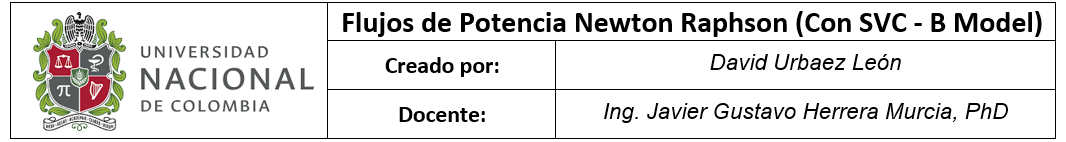

### 3)      Se crea Ybus con las redes de 2 puertos:

                Se tiene la siguiente red de dos puertos, que representa el circuito del modelo pi de la línea de transmisión

                                
$$\left\lbrack \begin{array}{c}
V_i \\
V_j 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\frac{1}{z}+\frac{y}{2} & -\frac{1}{z}\\
-\frac{1}{z} & \frac{1}{z}+\frac{y}{2}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
I_i \\
I_j 
\end{array}\right\rbrack$$


                                        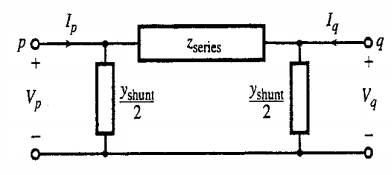

                       Pi-equvalent model of a transmission line  *(Pag 296, Bergen)*

n_br = size(br_data, 1); % Number of branches
num_nodes = max(max([br_data.FromBus,br_data.ToBus]));  % Number of nodes (starting at 1)
Ybus = zeros(num_nodes, num_nodes); % Empty Ybus Matrix

for kk = 1: size(br_data, 1)    % Iter over branch Data
    ii = br_data.FromBus(kk);               % From bus
    jj = br_data.ToBus(kk);                 % To Bus
    z = br_data.R(kk) + 1j * br_data.X(kk);  % Line impedance
    y = br_data.G(kk) + 1j * br_data.B(kk);  % Shunt admitance
    
    Ybr=[1 / z + y / 2 ,    -1 / z;  ...     % Ybr (Two-Port Network)
            -1 / z     , 1 / z + y / 2];

    Ybus([ii,jj],[ii,jj]) = Ybus([ii,jj],[ii,jj])+ Ybr;                       % Add the Two-Port Network to the global Ybus Matrix
end

Se extrae la información de las potencias y voltajes:

Vm_sp = N_data.Vm;              %   [V]  Specified Voltages
th_sp = N_data.Va.* pi ./ 180; % [Rads] Specified Angles
PG = N_data.PG;                 % [p.u.] Active Power generators
QG = N_data.QG;                 % [p.u.] Reactive Power generators

PL = N_data.PL;                 % [p.u.] Active Power Loads
QL = N_data.QL;                 % [p.u.] Reactive Power Loads

%% Calculated NetPowers
P_sp = PG - PL;                      % [p.u.] Specified Active Power    Pnet= (PGen - PLoad)
Q_sp = QG - QL;                      % [p.u.] Specified Reactive Power  Qnet= (QGen - QLoad)

### 4) Construcción de la matriz Jacobiana

Se encuentran las dimensiones de la matriz jacobiana:

% Jacobian matrix size.

nL = sum(strcmp(N_data.type,'PQ'));% Number of PQ nodes  (#Loads)
nG = sum(strcmp(N_data.type,'PV'));% Number of PV nodes  (#Generators)



Se divide la matriz Jacobiana en la submatrices H-N-M-L

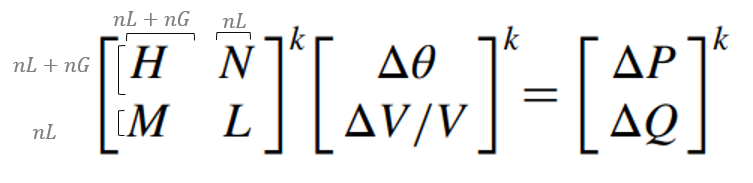

                                                                             *(Eq. 3.32, pag108, Gómez - Exposito)*

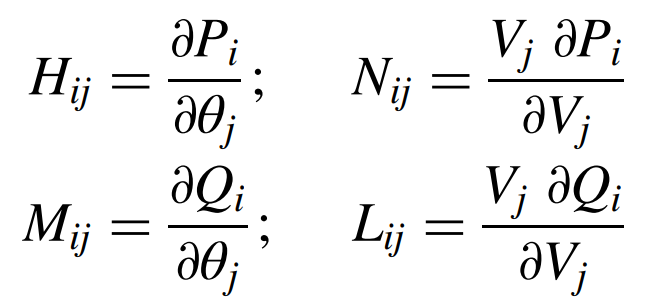

*                                                                     (Eq. 3.34, pag109, Gómez - Exposito)*

H = zeros( nL + nG, nL + nG );
L = zeros( nL, nL );
N = zeros( nL + nG , nL );
M = zeros( nL , nL + nG );
J = [H, N; M, L];

Se crea el vector de estados ($X={\left\lbrack \theta |V\right\rbrack }^T$) y el vector de funciones no lineales ($f\left(x\right)=\left\lbrack \Delta P|\Delta Q\right\rbrack$

x_th = zeros( nL + nG, 1 ); % State vector for storing angles (theta)
x_v = zeros( nL , 1);       % State vector for storing Voltages

     dim= (2nL+nG)

x = [x_th; x_v];

-     Donde se tiene que:

                        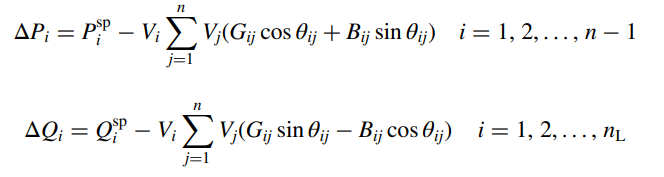

*                                                                                                                        (Eq. 3.30-3.31, pag108, Gómez - Exposito)*

Dt_P = zeros( nL + nG, 1 ); % Delta P 
Dt_Q = zeros( nL, 1);       % Delta Q

                dim= (2nL+nG)

Dt = [Dt_P;Dt_Q];  %Delta Vector (same as f(x) Vector)

%% Define Unkown Values (Voltage and angle in PQ node - Angle in PV node)

% #Buses with unknwon voltage magnitudes ('PQ' buses)  (Delta Q index)
x_v_n=N_data(strcmp(N_data.type,'PQ'),:).n;                          

% #Buses with unknwon voltage angles ('PQ'|'PV' buses) (Delta P index)
x_th_n=N_data(strcmp(N_data.type,'PV')|strcmp(N_data.type,'PQ'),:).n;


x_n = [x_th_n; x_v_n]; % #Buses with unknown Angles and unknown voltages

max_iter = 100; %Define Max iteration number

V = zeros(num_nodes, max_iter); % Matrix for storing node voltages per iter
Vm = zeros(num_nodes, max_iter);    % For storing node voltage magnitude per iter
th = zeros(num_nodes, max_iter);    % For storing node voltage angles per iter
V(:,1) = Vm_sp .* exp(1j .* th_sp); % Fill with initial Specified Voltages
Vm(:,1) = Vm_sp;                    % Fill with initial Specified Magnitud
th(:,1) = th_sp;                    % Fill with initial Specified Angle

err = 1.0;  % Define Error
k = 1;      % iteration counter

## 5) Inicia el método Newton Raphson


while (err > 1e-12 && k <= max_iter)
% for cc = 1 : 3
   
    % *************************** Jacobian Terms Calculation.
    Vn = V( : , k ); %Phasors!!
    Vd = diag( Vn ); %Voltages in a diagonal matrix
    
    % Calculate active and reactive power per node
    Sn = Vd * conj( Ybus * V( : , k ) ); %  Sn=V(I)* | I=Y_bus·V | Sn=V·(Ybus·V)*
    Pn = real(Sn);  %Active Power calculated
    Qn = imag(Sn);  % Reactive Power calculated

            Una vez se tiene el cálculo de las potencias, se procede a agregar el valor de potencia reactiva suministrada por el SVC.

    (eq 5.5, Acha)

    %% Calculate injected bus powers by the SVC 
    for ii = 1 : size(SVC_data,1)
        Qn(SVC_data{ii,"SVCBus"})=Qn(SVC_data{ii,"SVCBus"})-(Vm(SVC_data{ii,"SVCBus"}))^2*SVC_data{ii,"B"};
    end

    A continuación, se realiza el cálculo de las componentes del Jacobiano, para ello se obtienen las matrices H,L,N,M donde:

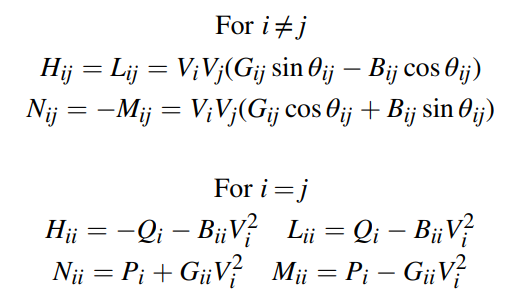

*                                                                                                                                                                                   (Table 3.1, pag109, Gómez - Exposito)*

  % H Matrix.   H -> Dim: (nL+nG) X (nL+nG)
    
    for mm = 1 : nL + nG        %Iter over rows H matrix
        for nn = 1 : nL + nG    %Iter over cols H matrix
            ii = x_th_n(mm);    % #node corresponding to row mm
            jj = x_th_n(nn);    % #node corresponding to column nn
            
            % From Prev Equations:
            if ii == jj
                H(mm,nn) = - Qn(ii) - imag( Ybus(ii,jj) ) .* abs( V(ii,k) ).^2;
            else
                H(mm,nn) = abs( V(ii,k) ) * abs( V(jj,k) ) .* ( ...
                    real(Ybus(ii,jj)) * sin( th(ii,k) - th(jj,k) ) - ...
                    imag(Ybus(ii,jj)) * cos( th(ii,k) - th(jj,k) ) );
            end
        end
    end
   
    % N Matrix. N -> Dim: (nL+nG) X (nL)
    for mm = 1 : nL + nG     %  Iter over rows N matrix
        for nn = 1 : nL      %  Iter over cols N matrix
            ii = x_th_n(mm); % #node corresponding to row mm
            jj = x_v_n(nn);  % #node corresponding to column nn
           
            % From Prev Equations:
            if ii == jj
                N(mm,nn) = Pn(ii) + real(Ybus(ii,jj)) .* abs(V(ii,k)).^2;
            else
                N(mm,nn) = abs( V(ii,k) ) * abs( V(jj,k) ) .* ( ...
                    real(Ybus(ii,jj)) * cos( th(ii,k) - th(jj,k) ) + ...
                    imag(Ybus(ii,jj)) * sin( th(ii,k) - th(jj,k) ) );
            end
        end
    end
   
    % M Matrix. M -> Dim: (nL) X (nL+nG)
    for mm = 1 : nL             %  Iter over rows M matrix
        for nn = 1 : nL + nG    %  Iter over cols M matrix
            ii = x_v_n(mm);     % #node corresponding to row mm
            jj = x_th_n(nn);    % #node corresponding to column nn
            
            % From Prev Equations:
            if ii == jj
                M(mm,nn) = Pn(ii) - real(Ybus(ii,jj)) .* abs(V(ii,k)).^2;
            else
                M(mm,nn) = -abs( V(ii,k) ) * abs( V(jj,k) ) .* ( ...
                    real(Ybus(ii,jj)) * cos( th(ii,k) - th(jj,k) ) + ...
                    imag(Ybus(ii,jj)) * sin( th(ii,k) - th(jj,k) ) );
            end
        end
    end
   
    % L Matrix. L -> Dim: (nL) X (nL)
    for mm = 1 : nL         %  Iter over rows L matrix
        for nn = 1 : nL     %  Iter over cols L matrix
            ii = x_v_n(mm); % #node corresponding to row mm
            jj = x_v_n(nn); % #node corresponding to column nn
            
            % From Prev Equations:
            if ii == jj
                L(mm,nn) = Qn(ii) - imag(Ybus(ii,jj)) .* abs(V(ii,k)).^2;
            else
                L(mm,nn) = abs( V(ii,k) ) * abs( V(jj,k) ) .* ( ...
                    real(Ybus(ii,jj)) * sin( th(ii,k) - th(jj,k) ) - ...
                    imag(Ybus(ii,jj)) * cos( th(ii,k) - th(jj,k) ) );
            end
        end
    end
   % The jacobian matrix results in:
    J = [H, N;...
        M, L];

Undefined function or variable 'SVC_data'.

            Posteriormente se hace la modificación de la matriz J del SVC (se reemplaza $\mathrm{Vsvc}\to \;\mathrm{Bsvc}$)

            

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
    %% SVC Jacobian Update
    
    for n = 1 : size(SVC_data,1)
        
%         PQ_Index = find(N_data(strcmp(N_data.type,'PQ'),:).n==SVC_data{ii,"SVCBus"});% get PQ index of the SVC*
        DQ_svc_Index =find(x_v_n==SVC_data{n,"SVCBus"});
        DP_svc_Index =find(x_th_n==SVC_data{n,"SVCBus"});
        if (SVC_data{n,'Status'} == 1)
            %Delete the voltage magnitud for the SVC bus
            J( : , nL+nG+DQ_svc_Index) = 0;  %Change DeltaV--->Delta B  (DeltaV=0 - SVC Condition V_svc=1p.u)
            
    %             JAC(2*SVCsend(ii)-1,2*SVCsend(ii)-1) = ...   % <- DeltaPk/Delta(Vangle)  
    %             JAC(2*SVCsend(ii)- 1,2*SVCsend(ii)-1)-VM(SVCsend(ii))^2*B(ii); %¿Error?
            
            J(DP_svc_Index,DP_svc_Index)=J(DP_svc_Index,DP_svc_Index)-Vm(SVC_data{n,"SVCBus"})^2*SVC_data{n,"B"};
            
            % [deltaQk] = [Qk]*[delta(Bsvc)/Bsvc]   --   k node= SVCnode
            J(nL+nG+DQ_svc_Index,nL+nG+DQ_svc_Index)= -Vm(SVC_data{n,"SVCBus"})^2*SVC_data{n,"B"}; 
            % [deltaQk]= J(nL+nG+PQ_Index,nL+nG+PQ_Index)
        end
    end
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 

Se calculan los términos residuales. (DP y DQ)

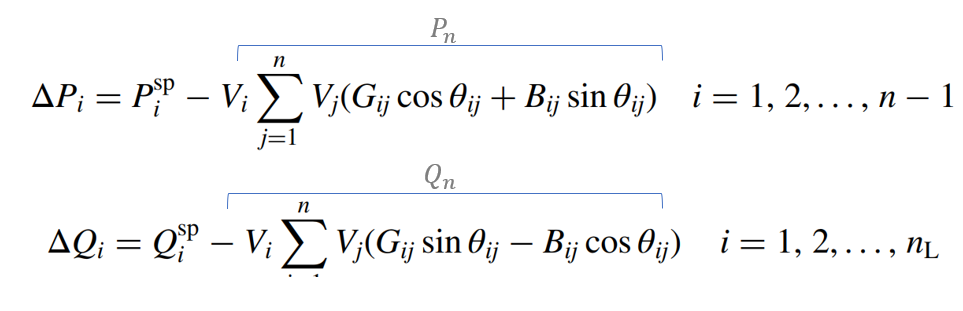


   % *************************** Residual Terms Calculations
   
    % Delta P
    Dt_P=P_sp(x_th_n(1:nL+nG))-Pn(x_th_n(1:nL+nG));
    % Delta Q
    Dt_Q=Q_sp(x_v_n(1:nL))-Qn(x_v_n(1:nL));

   
    Dt = [ Dt_P ;...
           Dt_Q ];
   

                    Se actualiza la solución del sistema donde:


$$\left\lbrack \begin{array}{c}
\theta_{k+1} \\
V_{k+1} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\theta_{k+1} \\
V_{k+1} 
\end{array}\right\rbrack +J^{-1} ·\left\lbrack \begin{array}{c}
\Delta P_k \\
\Delta Q_k 
\end{array}\right\rbrack$$


    % *************************** System Solution
    x = J\Dt; % Delta theta -> inv(J)*Dt
    x_th = x( 1 : nL + nG );                % Adjust in unknown Angles
    x_v = x( nL + nG + 1 : 2 * nL + nG );   % Adjust in unknown Voltages
   
    Vm(:,k + 1) = Vm(:,k); % new magnitudes
    th(:,k + 1) = th(:,k); % new Angles
   
    th(x_th_n, k + 1) = x_th + th(x_th_n, k); % New angle   =  Adjust in unknown Angle   + previus Angle
    Vm(x_v_n, k + 1)  = x_v.*Vm(x_v_n, k) + Vm(x_v_n, k);   % new voltage =  Adjust in unknown Voltage + previus Voltage 
                                                                     

 (Eq. 5.7, Acha)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%       SVC Update Adjust
    for ii = 1 : size(SVC_data,1)
        if (SVC_data{ii,'Status'}  == 1)
            
            DQ_Index= find(N_data(strcmp(N_data.type,'PQ'),:).n==SVC_data{ii,"SVCBus"});% get PQ index of the SVC*
            
            % Adjust the Voltage Magnitud target
            Vm(SVC_data{ii,"SVCBus"},k + 1) =SVC_data{ii,"Tv"}; %Voltage at SVCnode ->  Target Voltage(1 p.u.)
            
            % SVC Susceptance - Delta(Bsvc) 
            value = SVC_data{ii,"B"}*x(nL+nG+DQ_Index); % delta(Bsvc)
            value2 = x(nL+nG+DQ_Index);                 % delta(Bsvc)/Bsvc
            
            %% If high or low delta(Bsvc)
            if (value > 0.1) 
                value2 = 0.1/SVC_data{ii,"B"};  % max -> delta(Bsvc)/Bsvc per iteration
            elseif (value < -0.1)
                value2 = -0.1/SVC_data{ii,"B"}; % min -> delta(Bsvc)/Bsvc per iteration
            end
            
            % SVC Susceptance Update
            SVC_data{ii,"B"} = SVC_data{ii,"B"} + SVC_data{ii,"B"}*value2; % Ecn 5.7 Acha
        end
        
        
        % Check susceptance limits in SVC
    
        if (SVC_data{ii,"B"} > SVC_data{ii,"Bmax"})
            SVC_data{ii,"B"} = SVC_data{ii,"Bmax"};
        elseif (SVC_data{ii,"B"} < SVC_data{ii,"Bmin"})
            SVC_data{ii,"B"} = SVC_data{ii,"Bmin"};
        end
    end   
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


    V(:,k + 1) = Vm(:,k + 1) .* exp( 1j .* th(:,k + 1) ); % Calculate phasors.
    
    %err = max( abs( V(:,k+1) - V(:,k) )  );
    err = max( abs( Dt )  ); % Calculate error
   
    k = k + 1;  % Add 1 to iterations
    if(k>=max_iter)
        disp("max iter error")
        break
    end
end

###     6) Cálculos finales:

        Para el cálculo de la potencia aparente se tiene que:

        
$$S=\left\lbrack \begin{array}{cccc}
V_1  & 0 & 0 & 0\\
0 & V_2  & 0 & 0\\
0 & 0 & \ddots  & \vdots \\
0 & 0 & \cdots  & V_n 
\end{array}\right\rbrack ·{\left(Y_{\mathrm{Bus}} ·\left\lbrack \begin{array}{c}
V_1 \\
V_2 \\
\vdots \\
V_n 
\end{array}\right\rbrack \right)}^* =\left\lbrack \begin{array}{cccc}
V_1  & 0 & 0 & 0\\
0 & V_2  & 0 & 0\\
0 & 0 & \ddots  & \vdots \\
0 & 0 & \cdots  & V_n 
\end{array}\right\rbrack ·{\left(\left\lbrack \begin{array}{c}
I_1 \\
I_2 \\
\vdots \\
I_n 
\end{array}\right\rbrack \right)}^* =\left\lbrack \begin{array}{cccc}
V_1  & 0 & 0 & 0\\
0 & V_2  & 0 & 0\\
0 & 0 & \ddots  & \vdots \\
0 & 0 & \cdots  & V_n 
\end{array}\right\rbrack ·\left(\left\lbrack \begin{array}{c}
I_1^* \\
I_2^* \\
\vdots \\
I_n^* 
\end{array}\right\rbrack \right)=\left\lbrack \begin{array}{c}
V_1 I_1^* \\
{V_2 I}_2^* \\
\vdots \\
{V_n I}_n^* 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
S_1 \\
S_2 \\
\vdots \\
S_n 
\end{array}\right\rbrack$$


% Complex power calculation for each node.
Vn = V( : , k );
Vd = diag( Vn );
Sn = Vd * conj( Ybus * V( : , k ) );
Pn = real(Sn);
Qn = imag(Sn);

SGn = Sn + (PL + 1j * QL);
SLn = SGn - Sn;

% Complex Power Flow Through Branches.

S_pf = zeros( 2*size(br_data, 1) , 5);

bc = 1;
for kk = 1: size(br_data, 1)
    ii = br_data.FromBus(kk);
    jj = br_data.ToBus(kk);
    z = br_data.R(kk) + 1j * br_data.X(kk);
    y = br_data.G(kk) + 1j * br_data.B(kk);
    Ybr=[1 / z + y / 2 ,    -1 / z;  ...     % Ybr (Two-Port Network)
            -1 / z     , 1 / z + y / 2];
    S_br=diag([Vn(ii),Vn(jj)])*conj(Ybr*[Vn(ii);Vn(jj)]);
    
    S_pf_br= [ii, jj, real(S_br(1)), imag(S_br(1)), abs(S_br(1));...% Apparent power from i to j
              jj, ii, real(S_br(2)), imag(S_br(2)), abs(S_br(2))];  % Apparent power from j to i
    
    S_pf(2*kk-1:2*kk,:)=S_pf_br;
end



### 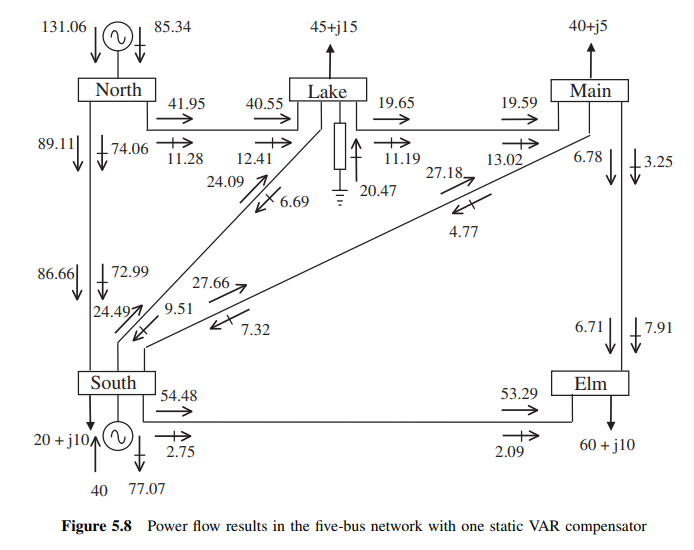

### Referencias:

[1] Gomez - Exposito,A. Electrica Energy Systems, Analysis and operation. 2nd Edition. Boca Raton : Taylor & Francis, CRC Press, 2018.

[2] Acha,E. FACTS Modelling and Simulation in Power Networks. 1st Edition. Boca Raton : John Wiley & Sons Inc,2004 